## **1.5 **Implementing a First-Order Difference Equation

    Discrete-time systems are often implemented with linear constant-coefficient difference equations. Two very simple difference equations are the first-order moving average

y[n] = x[n] + b * x[n - 1], *(1.5)*

and the first-order autoregression

y[n] = a * y[n - 1] + x[n]. *(1.6)*

    Even these simple systems can be used to model or approximate a number of practical systems. For instance, the first-order autoregression can be used to model a bank account, where y[n] is the balance at time n, x[n] is the deposit or withdrawal at time n, and a = 1 + r  is the compounding due to interest rate r. In this exercise, you will be asked to write a function which implements the first-order autoregression equation. You will then be asked to test and analyze your function on some example systems.

### Advanced Problems

#### **(a)**

    Write a function *y = diffeqn(a, x, yn1)* which computes the output y[n] of the causal system determined by Eq. (1.6). The input vector x contains x[n] for 0 <= n <= N - 1 and yn1 supplies the value of y[-1]. The output vector y contains y[n] for 0 <= n <= N - 1. The first line of your M-file should read

*function y = diffeqn(a, x, yn1)*

    **Hint**: Note that y[-1] is necessary for computing y[0], which is the first step of the autoregression. Use a for loop in your M-file to compute y[n] for successively larger values of n, starting with n = 0.

% diffequ.m can be seen at the end of this report.

#### **(b)**

    Assume that a = 1, y[-1] = 0, and that we are only interested in the output over the interval 0 <= n <= 30. Use your function to compute the response due to x1[n] = δ[n]  and x2[n] = u[n], the unit impulse and unit step, respectively. Plot each response using *stem*.

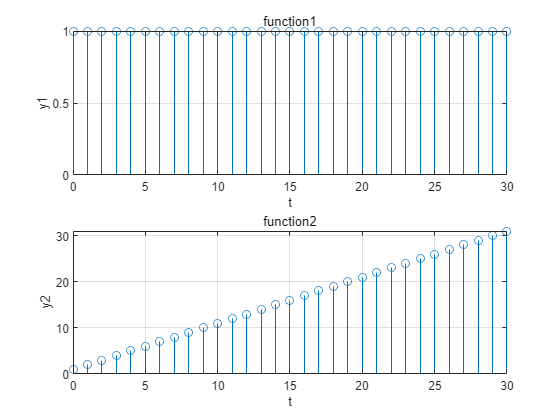

% 最好控制语句以外都加上分号
% clear;                        <-- 最好加个 clear
% yn1 = -1;                     <-- 按题设貌似是 yn1 = 0 ...?
% for i = 0:30                  <-- 生成 δ 和 u 可以用 ones(m,n) 和 zeros(m,n) 生成 m 行 n 列的全 1 或全 0 矩阵
%     x2(i+1)=1                     也可以用 (i >= 0) 和 (i == 0) 生成，这种表达式会分别对 i 每个元素检验，符合条件就会填上 1
%     if i==0
%         x1(i+1)=1
%     else x1(i+0)=0            <-- x1(i + 1) 误打成 + 0 了
%     end
% end
% y1=diffeqn(a,x1,yn1)          <-- 前面少定义 a = 1;
% y2=diffeqn(a,x2,yn1)
% i=[0:30];
% subplot(2,1,1)
% stem(i,y1);
% grid;
% tltle('function1');           <-- tltle -> title
% xlabel('t')                   <-- 离散信号一般标 n
% ylabel('y1')                  <-- 一张图后面再跟个 legend('图例');
% subplot(2,1,2)
% stem(i,y2);
% grid;
% title('function2')
% xlabel('t')
% ylabel(y2)                    <-- y2 -> 'y2'

clear;

a = 1;
yn1 = 0;

for i = 0 : 30
    x2(i + 1) = 1;
    if i == 0
        x1(i + 1) = 1;
    else
        x1(i + 1) = 0;
    end
end

y1=diffeqn(a,x1,yn1);
y2=diffeqn(a,x2,yn1);
i=0:30;
subplot(2,1,1);
stem(i,y1);
grid;
title('function1');
xlabel('t');
ylabel('y1');
subplot(2,1,2)
stem(i,y2);
grid;
title('function2')
xlabel('t')
ylabel('y2')

    **Conclusion** Text.

#### **(c)**

    Assume again that a = 1, but that y[-1] = -1. Use your function to compute y[n] over 0 <= n <= 30 when the inputs are x1[n] = u[n] and x2[n] = 2 * u[n]. Define the outputs produced by the two signals to be y1[n] and y2[n], respectively. Use *stem* to display both outputs. Use *stem* to plot (2 * y1[n] - y2[n]). Given that Eq. (1.6) is a linear difference equation, why isn't this difference identically zero?

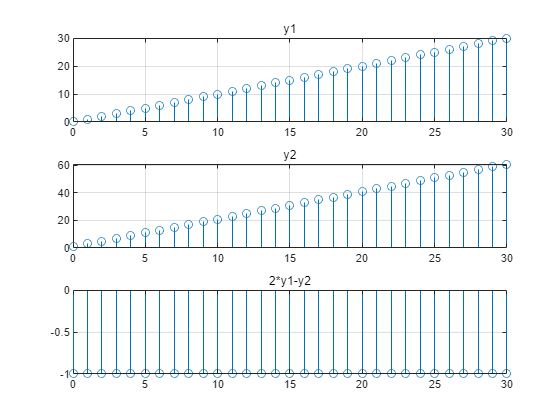

% 最好控制语句以外都加上分号
% clear;                    <-- clear
% a=1;yn=-1;                <-- yn -> yn1 (y negative 1)
% for i=0:30
%     x1(i+1)=1;
%     x2(i+2)=1;            <-- 应为 x2(i + 1) = 2; 是数乘不是时移
% end
% y1=diffeqn(a,x1,yn1)
% y2=diffeqn(a,x2,yn2)      <-- 前面定义的叫 yn1
% i=[0:30];                 <-- 可以不加括号
% subplot(311)              <-- 虽然也能用，不过最好还是逗号隔开。subplot(m,n,i) 指选中 m 行 n 列子图中的第 i 个
% stem(i,y1);
% grid;                     <-- 写 grid on; 表意清晰一些
% title('y1')               <-- 一般标注写在 xlabel 和 ylabel
% subplot(312)
% stem(i,y2);
% grid;
% title('y2');
% subplot(313)
% stem(i,2*y1-y2);
% grid;
% title('2*y1-y2');
% 还有 legend 图例

clear;

a=1;yn1=-1;
for i=0:30
    x1(i+1)=1;
    x2(i+1)=2;
end

y1=diffeqn(a,x1,yn1);
y2=diffeqn(a,x2,yn1);
i=0:30;
subplot(3,1,1);
stem(i,y1);
grid;
title('y1');
subplot(3,1,2);
stem(i,y2);
grid;
title('y2');
subplot(3,1,3);
stem(i,2*y1-y2);
grid;
title('2*y1-y2');

    **Conclusion** Text.

#### **(d)**

    The causal systems described by Eq. (1.6) are BIBO (bounded-input bounded-output) stable whenever |a| < 1. A property of these stable systems is that the effect of the initial condition becomes insignificant for sufficiently large n. Assume a = 1 / 2  and that x contains x[n] = u[n] for 0 <= n <= 30. Assuming both y[-1] = 0 and  y[-1] = 1 / 2, compute the two output signals y[n] for 0 <= n <= 30. Use *stem* to display both responses. How do they differ?

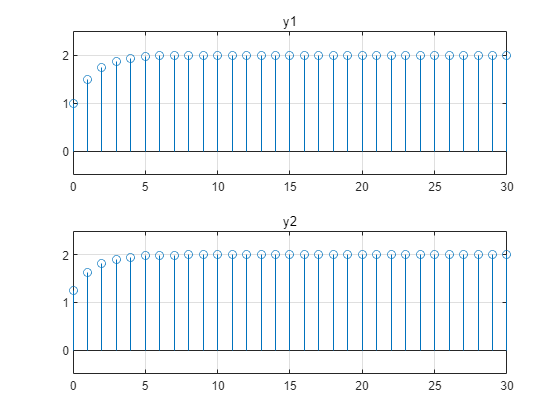

% 分号和图例
% clear;
% a=0.5
% yn1=0
% yn2=-1                    <-- 题设为 0.5
% for n=0:30;               <-- 不写在一行 for 后面可不加分号
%     x(n+1)=1;
% end
% y1=diffeqn(a,x1,yn1);     <-- 前面只定义了 x
% y2=diffeqn(a,x2,yn2);     <-- 同上
% n=[0:30];                 <-- 可不加括号
% subplot(211)
% stem(n,y1);
% grid;
% axis([0 30 -0.5 2.5]);
% title('y1');              <-- xlabel 和 ylabel 和 图例
% subplot(212)
% stem(n,y2);
% grid;
% axis([0 30 -0.5 2.5]);
% title('y2');
% 不过貌似可以画在一张图里

a=0.5;
yn1=0;
yn2=0.5;
for n=0:30
    x(n+1)=1;
end
y1=diffeqn(a,x,yn1);
y2=diffeqn(a,x,yn2);
n=0:30;
subplot(211);
stem(n,y1);
grid;
axis([0 30 -0.5 2.5]);
title('y1');
subplot(212);
stem(n,y2);
grid;
axis([0 30 -0.5 2.5]);
title('y2');

    **Conclusion** Text.

% function y = diffeqn(a,x,yn1)
%     n = length(x);
%     for i = 1 : n
%         if i == 1
%             y(i) = a * yn1 * x(i);            <-- a * yn1 加 x(i)
%         else
%             y(i) = a * y(i - 1) + x(i);
%         end
%     end
% end

function y = diffeqn(a,x,yn1)
    n = length(x);
    for i = 1 : n
        if i == 1
            y(i) = a * yn1 + x(i);
        else
            y(i) = a * y(i - 1) + x(i);
        end
    end
end